CODE ADDITIONS 

7/8/2026; 7:53 pm (Isaac)

- Implemented an image processing algorithm that (mostly) works for Tube images. It needs testing.

7/9/2026; 4:34 pm (Ryan)

- Updated Dataset organization so that each subfolders organization matches. Changed to imageDatastore and added class labels and pass/fail classification for each image.

7/11/2026; 4:14 pm (Ryan)

- Added corner removal to improve output decision reliability. Added comments to better explain which image is which when selected from the range (Tubes only).

7/12/2026; 10:52 am (Ryan)

- Added labels to ROI that correspond to each table entry for easier analysis of performance. Adjusted minimum eccentricity to improve detection of short tubes as anomalous.

Choose Data Subset of Interest

dataSubset = "tubes";
displayOrginalImage = true;

Current working algorithm

numObsPerClass = 4×2 table
         Label          Count
    ________________    _____

    color_mismatch         8 
    defective_length      13 
    good                 154 
    malformed_metal       50 


Number of Files: 225


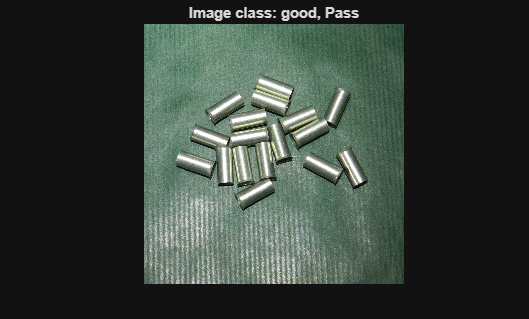

% Obtain the file location of the dataset. 
% ***IMPORTANT***
% This file location stored is a RELATIVE path!!!
% For this script to run, your active path must be set to where
% the MPDD dataset is stored on your local system.
%
% To change your active path, click the "Set Path" option under the
% "Environment" sub tab within the MATLAB application. 
fileLoc = sprintf("MPDD/%s", dataSubset);


% Creates an image Datastore to store all images of specified subset type.
% The image Datastore is setup to specifically look for images with certain file
% extensions that are common for images (i.e. jpg, png, etc.)
ds = imageDatastore(fileLoc, 'IncludeSubfolders',true, 'LabelSource','foldernames', ...
    'FileExtensions', ["*.jpg", "*.png", "*.tiff"]);

% Filter 'ground truth'/masks that are only used for model verification
excludeMask = contains(ds.Files, "gt*" | "mask");
ds = subset(ds, ~excludeMask);

% Obtain the number of files within the selected sub directory
numFiles = numel(ds.Files);

% ***Image processing begins here***
%
% Load the image of interest from the datastore object
% Color mismatch    01 - 008, + 21
% Defective Length  09 - 021
% Malformed Metal   22 - 071, + 8
% Good              72 - 225
imgNum = 102;
img = readimage(ds, imgNum);

% Labels image and (Optionally) Displays class & image info
% imgClass <-- Official label of the image
% imgPF <-- Whether or not the part would pass or fail
imgClass =  ds.Labels(imgNum); 
if imgClass ~= "good"
    imgPF = "Fail"; 
else
    imgPF = "Pass";
end

if displayOrginalImage
    numObsPerClass = countEachLabel(ds)
    imgInfo = sprintf("Image class: %s, %s", imgClass, imgPF);

    disp("Number of Files: " + numFiles);
    imshow(img);
    title(imgInfo);
end

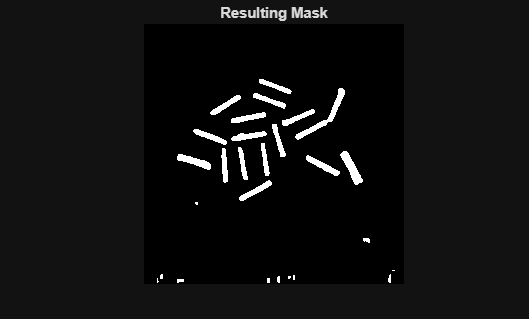


% Apply a grayscale filter to the selected image
%imgGS = im2gray(img);

% Display the original and grayscale images side by side
% disp("Color and Grayscale")
% imshowpair(img, imgGS, "montage");
% Extract the Green and Blue layers and use it as a mask to remove the
% background for better classification. 

% TO-DO: Find a way to determine which layer is better without having to perform both operations. From
% what I can see (Ryan), there appears to be a more significant tail in the
% mask that is better for removing the background, but I am unsure of how
% to remove it

%TO-DO SOLUTION (Isaac): Apply medium filter + adaptive thresholding filter
%to isolate objects. Tested on Tube sub dataset (needs to be tested on other objectss from other sub directories)

% Single Image Algorithm code to pre/post process TUBE images
% =========================================================================
% COLOR ANOMALY DETECTION (The Blue Tubes)
% =========================================================================
% Convert to HSV to safely isolate the blue paint. The H and S channels are
% sufficient for this step. (V channel controls brightness)
hsvImg = rgb2hsv(img);
hChannel = hsvImg(:,:,1);
sChannel = hsvImg(:,:,2);

% "Blue Tube" roughly means: Hue between 0.5-0.7, and high saturation
blueMask = (hChannel > 0.5) & (hChannel < 0.7) & (sChannel > 0.4);

% Clean up the mask to remove tiny blue glares or noise
blueMask = bwareaopen(blueMask, 500);
blueMask = imfill(blueMask, 'holes');

% Measure the colored tubes
colorStats = regionprops(blueMask, 'BoundingBox', 'Area');

% Track the number of color anomalies we found by counting the number of
% rows in the table. 
% We can ignore this section after we get this information.
numColorAnomalies = length(colorStats);

% =========================================================================
% SHAPE ANOMALY DETECTION (The Silver Tubes)
% =========================================================================
% Apply grayscale filter to the original image
gs = im2gray(img);

% Apply a medium filter to the image using a 15 pixel x 15 pixel size
% square to remove texture of the green background
% (i.e. to remove faded/scraped parts of the assembly line belt)
gsSmooth = medfilt2(gs, [15 15]);

% Apply adaptive thresholding to the previously medium-filtered image
% This calculates a threshold based on the local mean intensity of the
% vicinity of each pixel that is evaluated. 
% This actively searches for "bright", shiny surfaces (like the tubes)
% against the background. 
% The resulting threshold is then used with imbinarize() to create a binary
% image
T = adaptthresh(gsSmooth, 0.45, 'ForegroundPolarity', 'bright');
shapeMask = imbinarize(gsSmooth, T);

% Fill in "hole" regions within the tubes to make them appear solid on the
% mask using imfill()
% Remove small objects from the mask that are smaller than 500 pixels using
% bwareaopen()
shapeMask = imfill(shapeMask, 'holes');
shapeMask = bwareaopen(shapeMask, 500);

% Create a disk structural image with radius = 6 pixels
% to create an open image with the mask. This serves to address cases where
% tubes are falsely classified as one tube due to their close proximity.
breakSE = strel('disk', 6);
shapeMask = imopen(shapeMask, breakSE);

% Sets the corners of the image to 0 to prevent noise from affecting the
% image analysis
cornerSize = 50;
shapeMask(1:cornerSize, 1:cornerSize) = 0;
shapeMask(1:cornerSize, end-cornerSize:end) = 0;
shapeMask(end-cornerSize:end, 1:cornerSize) = 0;
shapeMask(end-cornerSize:end, end-cornerSize:end) = 0;

imshow(shapeMask);
title("Resulting Mask");

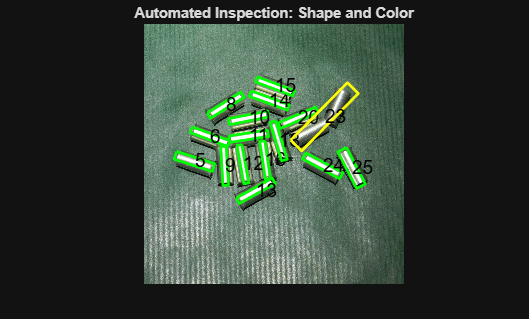


% Measure the shiny silver tubes based on the shape mask using
% regionprops()
% ***IMPORTANT***
%****************
% regionprops() objects serve as a structure that tracks several properties
% of images. In this case we are tracking:
% 1) Centroid --> To determine the center of each tube
%
% 2) MajorAxisLength --> To determine the length of each tube
%
% 3) MinorAxisLength --> To determine the width of each tube
%
% 4) Orientation --> To determine the angle at which each tube is oriented.
%                    This is for tightly fitting a rectangle to each tube
%                    in order to classify each object after processing is
%                    complete. Otherwise, the rectangles would be misplaced
%                    and not line up with each tube correctly.
%
% 5) Area --> To track how much Area each tube takes up in order to
%             determine a mean Area, to which other objects in the image
%             are compared against. Objects significantly smaller or larger than this
%             mean area are classified as anomalies. 
%
% 6) Eccentricity --> To  determine how "elongated" an object is. This
%                     address cases where the tube is cut off (i.e. similar width but much shorter), and hence
%                     significantly shorter than a standard size tube.
shapeStats = regionprops(shapeMask, 'Centroid', 'MajorAxisLength', 'MinorAxisLength', 'Orientation', 'Area', 'Eccentricity');

% Number each entry
for k = 1:length(shapeStats)
    shapeStats(k).Num = k;
end

% =========================================================================
% METRICS TRACKING & VISUALIZATION
% =========================================================================
figure;
imshow(img);
hold on;

% Initialize counters for the silver tubes
numShapeAnomalies = 0;
numNormalTubes = 0;

% Calibration variables for average tube area
% You must adjust these three numbers based on a "Good" image!
minNormalArea = 2000;         % Anything smaller than this is ignored as noise
maxNormalArea = 4800;       % Anything larger than this is flagged as crushed
minNormalEccentricity = 0.9; % Anything less elongated than this is flagged
maxNormalEccentricity = 0.999; % Anything more elongated than this is flagged

% Draw and Log Color Anomalies (From Pipeline 1)
for c = 1:numColorAnomalies
    % The below statements will plot red boxes over the tubes flagged as a
    % color anomaly.
    box = colorStats(c).BoundingBox;
    plot([box(1), box(1)+box(3), box(1)+box(3), box(1), box(1)], ...
         [box(2), box(2), box(2)+box(4), box(2)+box(4), box(2)], 'r-', 'LineWidth', 2);
end

% Draw and Log Shape Anomalies vs. Normal Tubes (From Pipeline 2) 
for k = 1:length(shapeStats)
    
    thisArea = shapeStats(k).Area;
    
    % Apply a noise filter using "historical" tube statistics that are set
    % as constants in this script (adjust as deemed necessary to fine tune
    % this part of the code)
    if thisArea < minNormalArea
        continue; 
    end
    
    thisEcc = shapeStats(k).Eccentricity;
    
    % Code to tightly fit a rectangle around each tube.
    center = shapeStats(k).Centroid;
    majorLen = shapeStats(k).MajorAxisLength;
    minorLen = shapeStats(k).MinorAxisLength;
    angle = -shapeStats(k).Orientation; 
    
    L = majorLen / 2; W = minorLen / 2;
    x = [-L,  L,  L, -L, -L]; y = [-W, -W,  W,  W, -W];
    
    theta = deg2rad(angle);
    R = [cos(theta), -sin(theta); sin(theta),  cos(theta)];
    rotCoords = R * [x; y];
    
    boxX = rotCoords(1, :) + center(1);
    boxY = rotCoords(2, :) + center(2);
    
    % Classify and count the number of normal and abnormal tubes
    if ((thisArea <= maxNormalArea) && (thisArea >= minNormalArea)) && ((thisEcc >= minNormalEccentricity) && thisEcc <= maxNormalEccentricity)
        plot(boxX, boxY, 'g-', 'LineWidth', 2); % Flag as Normal
        numNormalTubes = numNormalTubes + 1;
    else
        plot(boxX, boxY, 'y-', 'LineWidth', 2); % Flag as Anomaly
        numShapeAnomalies = numShapeAnomalies + 1;
    end

    % Label each with its corresponding number for easier data lookup
    % from the output table
    text(center(1), center(2), string(shapeStats(k).Num), "FontSize", 14, "Color", 'black');
end
hold off;
title('Automated Inspection: Shape and Color');

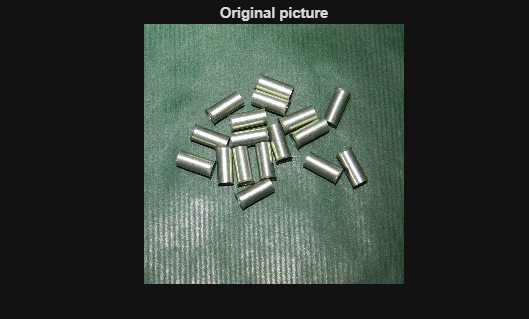


imshow(img);
title("Original picture");


% Print some results to the Command Window for troubleshooting purposes
totalTubesInImage = numNormalTubes + numShapeAnomalies + numColorAnomalies;

fprintf('\n--- Inspection Report: Image %d ---\n', imgNum);


--- Inspection Report: Image 102 ---


fprintf('Total Tubes Found:  %d\n', totalTubesInImage);

Total Tubes Found:  16


fprintf('Normal Tubes:       %d\n', numNormalTubes);

Normal Tubes:       15


fprintf('Shape Anomalies:    %d\n', numShapeAnomalies);

Shape Anomalies:    1


fprintf('Color Anomalies:    %d\n', numColorAnomalies);

Color Anomalies:    0


fprintf('-----------------------------------\n\n');

-----------------------------------





% Determine average values for tube statistics
averageArea = mean([shapeStats.Area]);
averageEccentricity = mean([shapeStats.Eccentricity]);

fprintf('Average Tube Area:      %.2f\n', averageArea);

Average Tube Area:      1902.04


fprintf('Average Tube Eccentricity: %.2f\n', averageEccentricity);

Average Tube Eccentricity: 0.89




shapeTable = struct2table(shapeStats);
disp(shapeTable);

    Area        Centroid        MajorAxisLength    MinorAxisLength    Eccentricity    Orientation    Num
    ____    ________________    _______________    _______________    ____________    ___________    ___

       7        11        51        8.0829             1.1547           0.98974               0       1 
     139    53.719    1011.9        24.355             8.0064           0.94442         -85.625       2 
     208        70     996.5        22.051             12.258           0.83126              90       3 
     383    142.32    1011.9        31.138             16.878           0.84036          1.7531       4 
    3811    199.45    541.96        158.47             32.369           0.97892         -17.817       5 
    2890    260.09    444.



% imgG = img(:,:,2); 
% imgGOpen = imopen(imgG, SE);
% disp("Green distribution");
% imhist(imgG);
% disp("Green image from grayscale")
% imshowpair(imgG, imgGOpen, "montage")
% 
% imgB = img(:,:,3);
% imgBOpen = imopen(imgB, SE);
% disp("Blue distribution");
% imhist(imgB);
% 
% maskG = imbinarize(imgGOpen, "global"); % background is bright (1s)
% disp("Grayscale and Opened")
% imshowpair(imgG, maskG, "montage");
% maskB = imbinarize(imgBOpen); % background is dark (0s)
% imshowpair(imgB, maskB, "montage");
% 
% % Use the Green Layer's mask
% mask = maskG;
% 
% imgNoBG = img .* cast(~mask, class(img));
% imgGSNoBG = imgGS;
% imgGSNoBG(mask) = 0;
% 
% disp("Color and Grayscale (No Background, Green)")
% imshowpair(imgNoBG, imgGSNoBG, "montage");
% 
% % Use the Blue Layer's mask
% mask = ~maskB;
% 
% imgNoBG = img .* cast(~mask, class(img));
% imgGSNoBG = imgGS;
% imgGSNoBG(mask) = 0;
% 
% disp("Color and Grayscale (No Background, Blue)")
% imshowpair(imgNoBG, imgGSNoBG, "montage");